% Loading in hourly of relevant variables
BuildingTab = load("CurrentBuildingVariables.mat");

NewBuildingTab = load("NewBuildingVariables.mat");

%Solar energy profile
WindTab = load("WindVariables.mat")

WindTab = struct with fields:
    HourlyDarrieusWind: [24×365 table]
        HourlyHAWTWind: [24×365 table]
    HourlySavoniusWind: [24×365 table]


SolarTab = load("SolarVariables.mat")

SolarTab = struct with fields:
    QuadHourlySolarEnergy: [24×365 table]
    RoofHourlySolarEnergy: [24×365 table]
    WallHourlySolarEnergy: [24×365 table]



BuildingTab.HourlyElectricalLoad(:,"29-Feb-2024: Thursday") = [];
BuildingTab.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
BuildingTab.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyElectricalLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];


% Comparison of loads
AnnualTotals = zeros(8,1);

AnnualTotals(1) = sum(sum(table2array(BuildingTab.HourlyElectricalLoad),1),2)

AnnualTotals = 1.0e+06 *

    1.0841
         0
         0
         0
         0
         0
         0
         0


AnnualTotals(2) = sum(sum(table2array(NewBuildingTab.HourlyElectricalLoad),1),2) 

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
         0
         0
         0
         0
         0
         0



OLDHourly_electrical_load_array=table2array(BuildingTab.HourlyElectricalLoad);
OLDHourly_heating_load_array=table2array(BuildingTab.HourlyHeatingLoad);
OLDHourly_cooling_load_array=table2array(BuildingTab.HourlyCoolingLoad);
OLDHourly_total_load_array=OLDHourly_electrical_load_array + ...
    (OLDHourly_heating_load_array./4) + ...
    (OLDHourly_cooling_load_array./4);


NEWHourly_electrical_load_array=table2array(NewBuildingTab.HourlyElectricalLoad);
NEWHourly_heating_load_array=table2array(NewBuildingTab.HourlyHeatingLoad);
NEWHourly_cooling_load_array=table2array(NewBuildingTab.HourlyCoolingLoad);
NEWHourly_total_load_array=NEWHourly_electrical_load_array + ...
    (NEWHourly_heating_load_array./4) + ...
    (NEWHourly_cooling_load_array./4);

AnnualTotals(3) = sum(sum(OLDHourly_total_load_array,1),2)

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
         0
         0
         0
         0
         0


AnnualTotals(4) = sum(sum(NEWHourly_total_load_array,1),2) 

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
    0.9511
         0
         0
         0
         0



AnnualTotals(5) = sum(sum(table2array(BuildingTab.HourlyHeatingLoad),1),2)

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
    0.9511
    0.1857
         0
         0
         0


AnnualTotals(6) = sum(sum(table2array(NewBuildingTab.HourlyHeatingLoad),1),2)

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
    0.9511
    0.1857
    0.1197
         0
         0



AnnualTotals(7) = sum(sum(table2array(BuildingTab.HourlyCoolingLoad),1),2)

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
    0.9511
    0.1857
    0.1197
    0.3461
         0


AnnualTotals(8) = sum(sum(table2array(NewBuildingTab.HourlyCoolingLoad),1),2)

AnnualTotals = 1.0e+06 *

    1.0841
    0.8673
    1.2171
    0.9511
    0.1857
    0.1197
    0.3461
    0.2154


% Plot showing the daily electrical load and wind generation from the
% Savonius wind turbine

DailyElectricalLoad = sum(NEWHourly_total_load_array,1);

DailySavoniusPower = sum(table2array(WindTab.HourlySavoniusWind),1);

DailySolarPower = sum(table2array(SolarTab.WallHourlySolarEnergy + SolarTab.RoofHourlySolarEnergy),1);
DailySolarPowerWithQuad = sum(table2array(SolarTab.WallHourlySolarEnergy + SolarTab.RoofHourlySolarEnergy + SolarTab.QuadHourlySolarEnergy),1);

% AnnualGen = zeros(3,1);
% 
% sum(DailyElectricalLoad);
% sum(DailySavoniusPower);

% AnnualGen(1) = sum(DailySavoniusPower).*9.*0.5
% AnnualGen(2) = sum(DailySolarPower)
% AnnualGen(3) = sum(DailySolarPowerWithQuad)

AnnualWindGen = zeros(2,1);
AnnualWindGen(1) = sum(DailySavoniusPower)

AnnualWindGen = 1.0e+04 *

    5.9567
         0


AnnualWindGen(2) = sum(DailySavoniusPower).*9.*0.5

AnnualWindGen = 1.0e+05 *

    0.5957
    2.6805



AnnualSolarGen = zeros(4,1);
AnnualSolarGen(1) = sum(sum(table2array(SolarTab.RoofHourlySolarEnergy),1),2)

AnnualSolarGen = 1.0e+05 *

    4.0142
         0
         0
         0


AnnualSolarGen(2) = sum(sum(table2array(SolarTab.WallHourlySolarEnergy),1),2)

AnnualSolarGen = 1.0e+05 *

    4.0142
    0.1806
         0
         0


AnnualSolarGen(3) = sum(sum(table2array(SolarTab.QuadHourlySolarEnergy),1),2)

AnnualSolarGen = 1.0e+05 *

    4.0142
    0.1806
    1.0036
         0


AnnualSolarGen(4) = sum(AnnualSolarGen(1:3));
    

sum(DailySavoniusPower).*9.*0.5/sum(DailyElectricalLoad) %Can fit approx 18 wind turbines - 50% efficiency?

ans = 0.2818

sum(DailySolarPower)/sum(DailyElectricalLoad)

ans = 0.4411

% Monthly Wind & Electrical Powers

% Step 1: Define the year
year = 2024;

% Step 2: Get months and number of days in each month
months = 1:12; % Months from January to December
daysInMonth = zeros(1, 12); % Initialize an array to hold the number of days
for m = months
    daysInMonth(m) = eomday(year, m); % Get the number of days in the month
end
daysInMonth(2) = 28;

% Step 3: Display the results
monthNames = month(datetime(year, months, 1), 'name'); % Get month names
index = 1;

MonthlyWindPower = zeros(1, 12);
MonthlyElectricity = zeros(1, 12);
MonthlySolarPower = zeros(1,12);
MonthlySolarPowerWithQuad = zeros(1,12);

for i=1:length(months)
    PerMonthWind = 0;
    PerMonthElecLoad = 0;
    PerMonthSolar = 0;
    PerMonthSolarWithQuad = 0;
    for j=1:daysInMonth(i)
        PerMonthWind = PerMonthWind + DailySavoniusPower(index)*18*0.5; %Can fit approx 18 wind turbines - 50% due to wake losees
        PerMonthElecLoad = PerMonthElecLoad + DailyElectricalLoad(index);
        PerMonthSolar = PerMonthSolar + DailySolarPower(index);
        PerMonthSolarWithQuad = PerMonthSolarWithQuad + DailySolarPowerWithQuad(index);
        index = index + 1;
    end
    MonthlyWindPower(i) = PerMonthWind;
    MonthlyElectricity(i) = PerMonthElecLoad;
    MonthlySolarPower(i) = PerMonthSolar;
    MonthlySolarPowerWithQuad(i) = PerMonthSolarWithQuad;
end


% Plot colours: 
colours = [[0 0.4470 0.7410],
    [0.8500 0.3250 0.0980],
    [0.9290 0.6940 0.1250],
    [0.4940 0.1840 0.5560],
    [0.4660 0.6740 0.1880],
    [0.3010 0.7450 0.9330],
    [0.6350 0.0780 0.1840]];

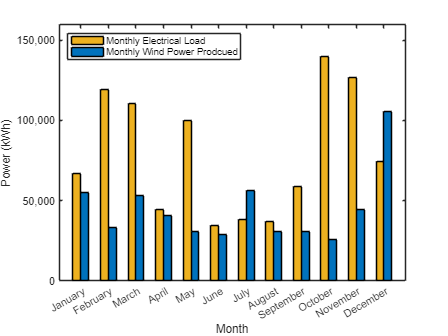

% Wind Plot

figure;
data = [MonthlyElectricity' MonthlyWindPower'];
hold on
b = bar(monthNames, data, 'BarWidth', 1);
b(1).FaceColor = colours(3,:);
b(2).FaceColor = colours(1,:);
hold off
box on

legend(["Monthly Electrical Load","Monthly Wind Power Prodcued"],'Location','northwest');
%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f')
ylabel("Power (kWh)")%,FontSize=28);
xlabel("Month")%,FontSize=28);
ylim([0,max(MonthlyElectricity,[],'all')+20000])

ax = gca;
exportgraphics(ax,'MonthlyWindVsLoad.eps','Resolution',300) 

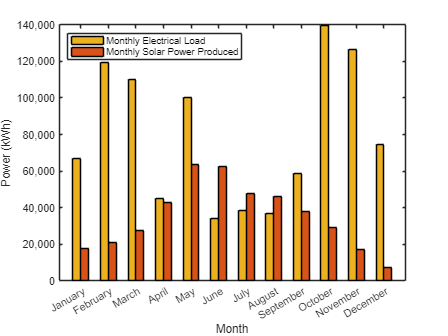

% Monthly Solar Plot

figure;
data = [MonthlyElectricity' MonthlySolarPower'];
hold on
b = bar(monthNames, data, 'BarWidth', 1);
b(1).FaceColor = colours(3,:);
b(2).FaceColor = colours(2,:);
hold off
box on

legend(["Monthly Electrical Load","Monthly Solar Power Produced"],'Location','northwest');
%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f')
ylabel("Power (kWh)")%,FontSize=28);
xlabel("Month")%,FontSize=28);

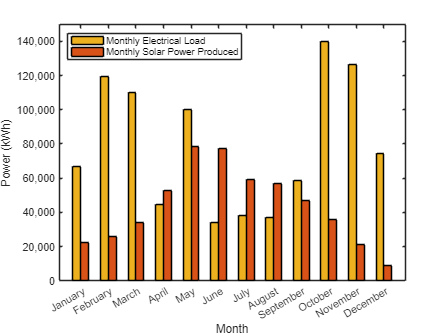

% Monthly Solar Plot with Quad Solar

figure;
data = [MonthlyElectricity' MonthlySolarPowerWithQuad'];
hold on
b = bar(monthNames, data, 'BarWidth', 1);
b(1).FaceColor = colours(3,:);
b(2).FaceColor = colours(2,:);
hold off
box on

legend(["Monthly Electrical Load","Monthly Solar Power Produced"],'Location','northwest');
%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f')
ylabel("Power (kWh)")%,FontSize=28);
xlabel("Month")%,FontSize=28);
ylim([0,max(MonthlyElectricity,[],'all')+10000])

ax = gca;
exportgraphics(ax,'MonthlySolarVsLoad.eps','Resolution',300) 

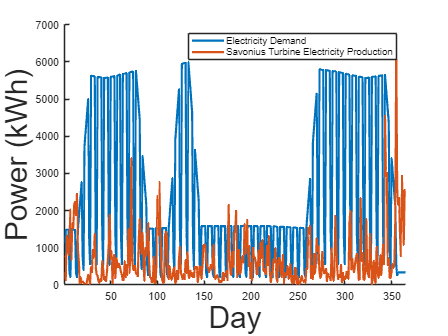


%% Superseded!!!!
figure;
hold on
plot(1:length(DailyElectricalLoad),DailyElectricalLoad,'LineWidth',2);
plot(1:length(DailySavoniusPower),DailySavoniusPower.*4,'LineWidth',2);
hold off

legend('Electricity Demand','Savonius Turbine Electricity Production');
xlabel('Day',FontSize=28);
ylabel('Power (kWh)',FontSize=28);
xlim([1 365]);